***Ejemplo: ***

Considere la siguiente funcion y calcule el polinomio iterante de Newton.

f = @(x) (x.^3+sin(x))./(exp(x)+15) %La funcion a trabajr

f = function_handle with value:
    @(x)(x.^3+sin(x))./(exp(x)+15)



X = [-2.8 -1.1 2.4 5.1] % Nodos

X =    -2.8000   -1.1000    2.4000    5.1000


Y = f(X) % Imagenes de los nodos

Y =    -1.4798   -0.1449    0.5572    0.7358


La rutina del Pol Newton da un vector "C" que contiene los valores para el polinomio de newton. 

El vector "D" de la rutina  es la matriz con las diferencias divididas (a_i) como se realizan en los videos de clase.

[C, D] = newpoly (X, Y)

C =     0.0115   -0.0952    0.2746    0.2876


D =    -1.4798         0         0         0
   -0.1449    0.7852         0         0
    0.5572    0.2006   -0.1124         0
    0.7358    0.0662   -0.0217    0.0115


El polinomio es de la forma 0.0115*x^3-0.0952*x^2+0.2746*x+0.2876

Grafiquemos la situacion dada para entender lo que está sucediendo.

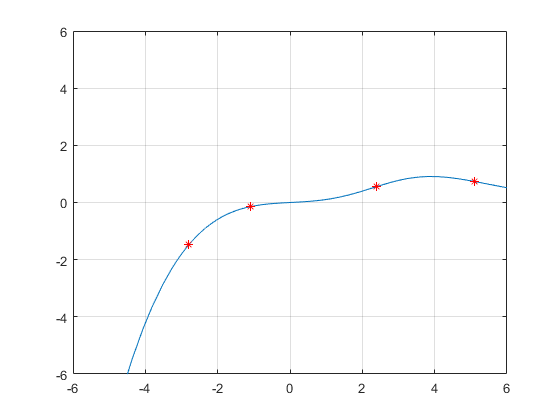

fplot(f) % Grafica la fn a trabajar
hold on
plot(X,Y, "*r") % Nodos en la grafica, puntos rojos
axis([-6 6 -6 6])
grid on
hold off % Esta grafica es la fn y los nodos que queremos aproximar

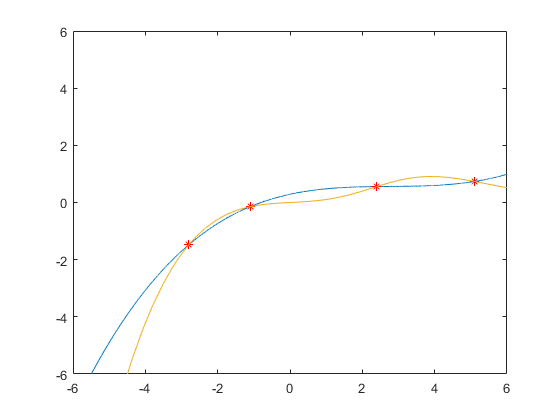

% Esta es la grafica del polinomio de Newton. Comparemos en uno solo
hold off

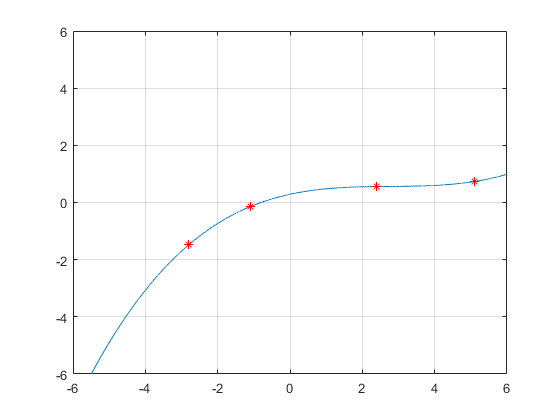

xx = linspace(-6,6,10000); % Grafique esta nube de puntos en el intervalo trabajado
yy = polyval(C,xx); %Evalue la nube de puntos y guardelos en yy
plot(xx,yy) %Grafica de los puntos 
hold on 
grid on
plot(X,Y,"*r") % Nodos graficados
axis([-6 6 -6 6])
hold off

Uniendo las dos graficas...

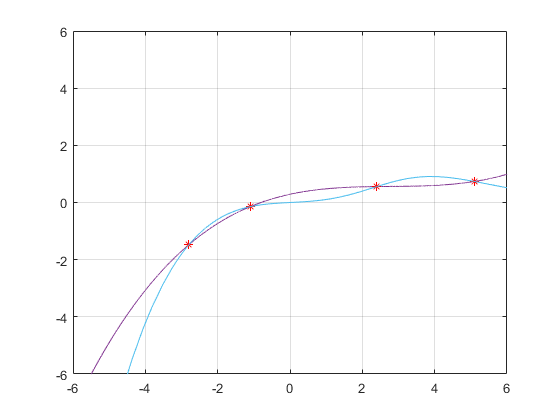

grid on
xx = linspace(-6,6,10000); % Grafique esta nube de puntos en el intervalo trabajado
yy = polyval(C,xx); %Evalue la nube de puntos y guardelos en yy
plot(xx,yy) %Grafica de los puntos 
hold on 
plot(X,Y,"*r") % Nodos graficados
fplot(f)
axis([-6 6 -6 6])